# PTn-Strecken

PTn-Strecken sind Verzögerungen höherer Ordnung. Diese entstehen durch Hintereinandrreihung von mehreren PT1-Strecken. Eine mögliche PTn-Strecke stellt z.B. die Serienschaltung verschiedener Teilstrecken eines Heizkreises dar: (i) Heizelement/Heizwendel (K1=1, T1=1), (ii) Metallkörper (K1=1, T1=1.5), (iii) Luft (K1=1, T1=3).

Der Übertragungsbeiwert des Heizelements wird im Regelfall einen Übertragungsbeiwert ungleich Eins haben (Spannung->Temperatur) - zur übersichtlichen Darstellung wird in der Übung tortzdem ein Übertragungsbeiwert von Eins angenommen. Für die beiden nachgeschalteten Teilstrecken ist es sinnvoll einen Übertragungsbeiwert von Eins anzunehmen, da die Ein- und Ausgangstemperaturen letztlich gleich sein werden.

clear all, close all, clc

## Übertragungsfunktionen der einzelnen PT1-Strecken

Erstellen Sie ein PTn-Strecken-Modell (Übertragungsfunktion) des obigen Heizkreises durch Serienschaltung der drei PT1-Strecken.

s = tf('s'); % komplexe Frequenz


k1 = 1;
t1 = 1;
g1 = k1 / (1+s*t1); % Heizelement

k2 = 1;
t2= 1.5;
g2 = k2 / (1+s*t2); % Metall

k3 = 1;
t3 = 3;
g3 = k3 / (1+s*t3); % Luft

## Sprungantwort und Frequenzgang der einzelnen PT1-Strecken

Stellen Sie die Sprungantworten und die Frequenzgänge der einzelnen PT1-Strecken in jeweils einem Diagramm dar. Fügen Sie den Diagrammen mit dem Befehl legend('show', 'Location', 'southeast') eine Legende hinzu.

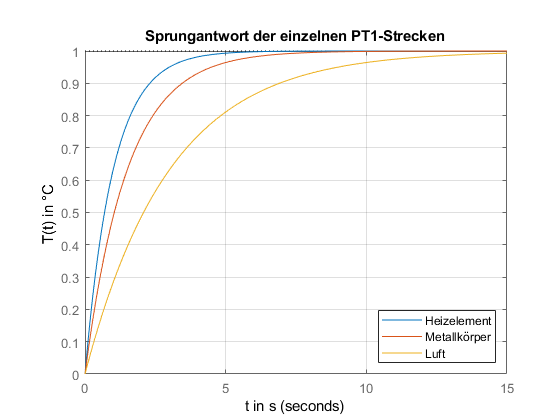

Tend = 5 * t3; % Simzeit mit längester Zeitkonst

step(g1, g2, g3, Tend), grid on
legend('Heizelement', 'Metallkörper', 'Luft', 'Location', 'southeast')
title('Sprungantwort der einzelnen PT1-Strecken')
xlabel('t in s'), ylabel('T(t) in °C')

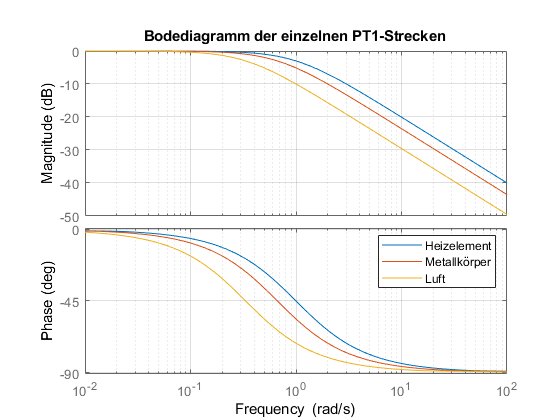

bode(g1, g2, g3), grid on
legend('Heizelement', 'Metallkörper', 'Luft', 'Location', 'northeast')
title('Bodediagramm der einzelnen PT1-Strecken')

## PTn-Strecke aus einer Serienschaltung von PT1-Strecken

Erzeugen sie nun durch die Hintereinanderschaltung der einzelnen PT1-Strecken eine PTn-Strecke und stellen Sie die Sprungantworten der einzelnen Streckenabschnitte sowie deren Frequenzgänge dar.

Anmerkung: Werden Strecken in Reihe geschaltet, so multiplizieren sich deren Übertragungsfunktionen.

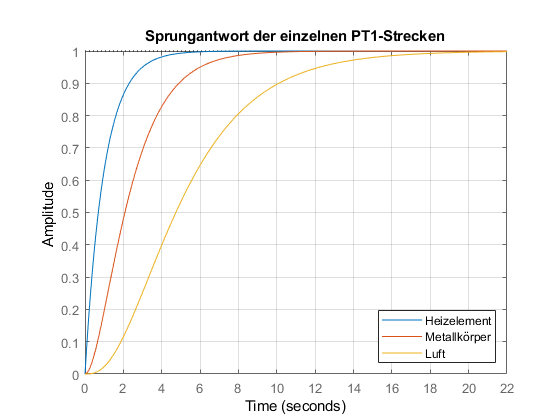

% Übertragungsfunktionen der Streckenabschnitte
Tend = (t1+t2+t3)*4;

%<ToDo />
g12 = g1 * g2;
g123 = g12 * g3;

% Diagramm der Sprungantworten

%<ToDo />
step(g1, g12, g123, Tend), grid on
legend('Heizelement', 'Metallkörper', 'Luft', 'Location', 'southeast')
title('Sprungantwort der einzelnen PT1-Strecken')

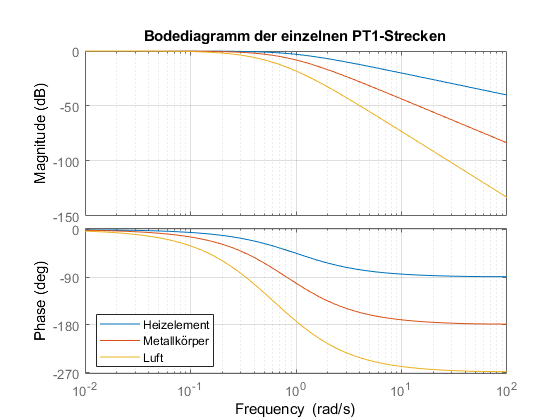


% Diagramm der Frequenzgänge

%<ToDo />
bode(g1, g12, g123), grid on
legend('Heizelement', 'Metallkörper', 'Luft', 'Location', 'southwest')
title('Bodediagramm der einzelnen PT1-Strecken')

## Empirische Bestimmung der Modellparameter einer PTn-Strecke

Als vereinfachtes **Modell der PTn-Strecke** wird angenommen, dass n gleichartige PT1-Strecken hintereinander geschaltet werden.

GPTn = K * 1/(1+s*T1) * 1/(1+s*T1) * ... * 1/(1+s*T1) = K/(1+s*T1)^n

% Im Regelfall sind die einzelnen Streckenteile nicht getrennt zugänglich und können
% damit nicht einzelnen charakterisiert werden. Gemessen werden kann nur die
% Sprungantwort des Gesamtsystems G123=X3/Y wobei Gs=G123=G1*G2*G3 entspricht.
%
% *Ermittlung der Modellparameter aus der Sprungantwort*: Eine PTn-Strecke wird durch
% die sogenannte Verzögerungszeit (Tu) und die Ausgleichzeit (Tg) charakterisiert.
% Dazu wird eine Wendetangente an die Kurve angelegt und die Schnittpunkte der
% Wendetangente mit der obern und unteren horizontalen Asymptote bestimmt.

% Ermitteln sie aus der simulierten Sprungantwort der PTn-Strecke die Ordnung der
% Strecke, die Verzugs- und die Ausgleichzeit sowie den Übertragungsbeiwert. Führen
% Sie die Konstruktion im Diagramm durch und speichern Sie dieses mit der Bezeichnung
% 'PTn_Strecke.fig' im aktuellen Arbeitsverzeichnis ab.

% openfig('PTn_Strecke.fig') % Bild der Konstruktion einfügen (Kommentar entfernen)

% Verzugs- und Ausgleichzeit (aus Konstruktion) und Tg/Tu-Verhältnis (berechnen)

%<ToDo />
dy = 1;
dx = 1;
Ks = dx/dy;
Ks = 1; %Übertragungsbeiwert
Tu = 1.289;
Tg = 8.285 - Tu;
TgTu = Tg / Tu % Zeitverhältnis (Maß für Regelbarkeit)

TgTu = 5.4275

disp( sprintf('Tu=%.2fs  Tg=%.2fs Tg/Tu=%.2f', [Tu Tg TgTu]) )

Tu=1.29s  Tg=7.00s Tg/Tu=5.43




%  Tg/Tu | Tg/T1 | Tu/T1 |  n  
% ------------------------------
%  9.61  | 4.48  | 3.13  |  2.44 
%  2.03  | 1.75  | 1.56  |  1.41 
%  1.29  | 2.72  | 3.69  |  4.46 
%  5.12  | 5.70  | 6.23  |  6.71 
%  7.16  | 7.59  | 0.28  |  0.80 
%  1.42  | 2.10  | 2.81  |  3.55 
%  4.30  | 5.08  | 5.87  |  2.00 
%  3.00  | 4.00  | 5.00  |  6.00 
%  7.00  | 8.00  | 9.00  | 10.00 
% Tabelle ist falsch
n = 3;
TgT1 = 3.5; % Schätzwert
TuT1 =  0.7; %Schätzwert
T1g = Tg / TgT1

T1g = 1.9989

T1u = Tu / TuT1

T1u = 1.8414

T1gu = (T1g + T1u) / 2

T1gu = 1.9201

%<ToDo />




% Diesen Block auskommentieren, um die errechneten Werte anzuzeigen!
disp( sprintf('Messung: Tu=%.2fs  Tg=%.2fs -> Tg/Tu=%.2f', [Tu Tg TgTu]) )

Messung: Tu=1.29s  Tg=7.00s -> Tg/Tu=5.43


disp( sprintf('Tg/T1=%.2f (T1g=%.2fs)', [TgT1 T1g]) )

Tg/T1=3.50 (T1g=2.00s)


disp( sprintf('Tu/T1=%.2f (T1u=%.2fs)', [TuT1 T1u]) )

Tu/T1=0.70 (T1u=1.84s)


disp( sprintf('n=%.1f  T1gu=%.2f  Ks=%.2f', [n T1gu Ks]) )

n=3.0  T1gu=1.92  Ks=1.00


## Gegenüberstellung PTn-Strecke und PTn-Ersatzstrecke

Stellen die folgenden Sprungantworten in einem Diagramm dar: (i) tatsächliche PTn-Strecke, (ii) PTn-Ersatzstrecke.

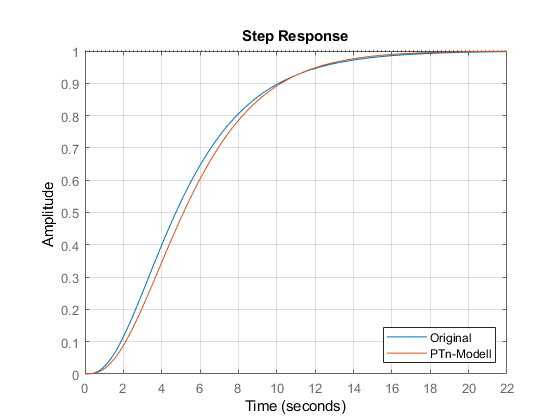

%<ToDo />
Gptn = Ks/(1+s*T1gu)^n;
step(g123, Gptn, Tend), grid on, legend('Original', 'PTn-Modell', 'Location', 'southeast')

## Führungsgrößensprung für Regelkreis mit P-Regler

Die PTn-Strecke soll mit einem P-Regler geregelt werden. Stellen sie die Sprungantwort für einen Führungsgrößensprung dar, wobei die Reglereinstellung mit den folgenden drei unterschiedlichen Werten erfolgen soll.

vKp = [0.5 1 2];


%<ToDo />